clear all
close all

%Define initial values of variables
x_initial = [50, 20, 10, 32, 100, 205, 12, 300, 120, 250, 56, 73, 15, 30, 10, 8, 50000000, 0.5, 20, 80, 44]

x_initial = 1.0e+07 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    5.0000    0.0000    0.0000    0.0000    0.0000



% Define Drag Coefficient Regression:
global cd_mdl
%Variables: [angle_alpha, angle_beta, angle_gamma, num_cars]
%Solutiuon: [Coefficient of Drag]
var = [15,30,10,3;15,15,10,3;50,30,20,3;15,50,20,3;15,15,10,7;30,50,10,15;15,15,20,7;15,30,10,15;50,50,10,3;30,15,20,3;50,30,20,7;15,15,20,3]; 
sol = [0.7306;0.49511;0.603478;0.865479;0.825286;1.33042;0.7927;1.16979;0.869678;0.51569;1.02362;0.438809];
cd_mdl=fitlm(var,sol);

% % %load earthquake data for 6 months in japan (9/27/2024 ~ 3/26/2025)
% earthquake_data_sorted = load("earthquake_data_sorted.mat");
% data = earthquake_data_sorted.earthquakes;

%test costObj function
[totalCost] = costObj(x_initial)

totalCost = single
943208704


%Run GA
%%% Set lower and upper bounds
%lower and upper bounds for train optimization
lb_network = [1,1,1,1,1,1,1,1,1,1,1,1];
ub_network = [133,307,133,307,133,307,133,307,133,307,133,307];

%lower and upper bounds for train optimization
lb_train =[15,15,10,3];
ub_train =[50,50,20,15];

%lower and upper bounds for safety optimization
lb_safety = [0 0 0 0 25];
ub_safety = [5000000000 1 60 200 100];

%Set overall lower and upper bounds
lb_total = [lb_network, lb_train, lb_safety] 

lb_total =      1     1     1     1     1     1     1     1     1     1     1     1    15    15    10     3     0     0     0     0    25


ub_total = [ub_network, ub_train, ub_safety]

ub_total = 1.0e+09 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    5.0000    0.0000    0.0000    0.0000    0.0000


%%% Set GA parameters
lb = lb_total;
ub = ub_total;
intcon = [1,2,3,4,5,6,7,8,9,10,11,12,16]; 
nvars = 21;
nonlincon = @combinedNonlincon;
fun = @costObj;

%Vmax_placeholder = 10;
%numcars_placeholder = 16;

%setGlobalVars(Vmax_placeholder,numcars_placeholder)

%intcon for network and safety 
intcon_network = [1, 2, 3, 4,5, 6, 7,8,9,10,11,12,16];
intocon_train = [4];

%options copied from Quinn's code:
options = optimoptions('ga', ...
    'Display', 'iter', ...                          
    'PlotFcn', {@gaplotbestf, @gaplotbestindiv}, ... 
    'UseParallel', false, ...                        % switched to false
    'PopulationSize', 120, ...
    'EliteCount', ceil(0.15 * 120), ...             % 15% of population kept as elite
    'CrossoverFraction', 0.70, ...                   % 70% of population undergoes crossover
    'CrossoverFcn', @crossoverlaplace, ...          % good for real-valued obj funcs
    'MutationFcn', @mutationadaptfeasible, ...      % adaptive mutation but only in the feasible space
    'SelectionFcn', @selectiontournament, ...       % tournament selection
    'MaxGenerations', 120, ...
    'FunctionTolerance', 1e-2, ...                  % stop if improvement in func value is very small
    'ConstraintTolerance', 1e-6, ...                % tight, but not zero, tolerance on constraints -->changed from 1e-3 to 0
    'InitialPenalty', 5, ...
    'PenaltyFactor', 100, ...                       % quickly increase penalties for violating constraints
    'MaxStallGenerations', 20);                     % stop if no improvement (beyond tolerance) after 20 generations

%Run GA
[x_star,fval,exitflag,output,population,scores] = ga(fun,nvars,[],[],[],[],lb,ub,nonlincon,intcon,options);


Single objective optimization:
21 Variables
13 Integer variables
32 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              240        0.002221          0.4234        0
    2              360        0.002221          0.2513        1
    3              480        0.002221          0.1504        2
    4              600        0.002221          0.1395        3
    5              720       1.343e+09       1.343e+09        4
    6              840       1.343e+09       1.343e+09        5


    7              960       1.214e+09        1.38e+09        0
ga stopped by the output or plot function. The reason for stopping: 
Stop requested from plot function.


%take output from ga and put it here 
x_star_train_network = [120	181	32	234	16	77	109	146	34	195	21	281	31.17124424	28.8394559	15.76329319	4];

%Initial Conditions
B = 50000000; %watt hours
A = 0.5;
S = 20; %[seconds]
t = 80; %ratio of speed to magnitude? [magnitude/meters/second]
V = 44; %max speed NEW
x0 = [B, A, S, t, V];

%lower and upper bounds for X
lb = [0 0 0 0 25];
up = [5000000000 1 60 200 100];

%run pattern search w/ starting point x0
[x_star,fval,exitflag,output] = patternsearch(@accident_count_function2,x0, [],[],[],[],lb,up)

x_total = [x_star_train_network, x_star]
totalCost = costObj(x_total)

%calculate individual scores
convenience_score = networkScore(x_star(1:12))

convenience_score = single
-0.3995

train_veloc = TrainVelocity(predict(cd_mdl,x_star(13:16)))

train_veloc = 61.4961

number_of_accidents = accident_count_function(x_star(16:21))

number_of_accidents = 10.9431


fval_individual = [convenience_score, train_veloc, number_of_accidents];

%calculate individual costs
network_cost = networkCost(x_star(1:12))

network_cost = single
498726752

train_cost = TrainCost(x_star(16))

train_cost = 192500000

safety_cost = safety_system_cost_function(x_star(17:21))

safety_cost = 5.5643e+08

costs_individual = [network_cost, train_cost, safety_cost]

costs_individual = 1×3 single row vector
   498726752   192500000   556432640


%options copied from Quinn's code:
options = optimoptions('ga', ...
    'Display', 'iter', ...                          
    'PlotFcn', {@gaplotbestf, @gaplotbestindiv}, ... 
    'UseParallel', false, ...                        % switched to false
    'PopulationSize', 120, ...
    'EliteCount', ceil(0.15 * 120), ...             % 15% of population kept as elite
    'CrossoverFraction', 0.70, ...                   % 70% of population undergoes crossover
    'CrossoverFcn', @crossoverlaplace, ...          % good for real-valued obj funcs
    'MutationFcn', @mutationadaptfeasible, ...      % adaptive mutation but only in the feasible space
    'SelectionFcn', @selectiontournament, ...       % tournament selection
    'MaxGenerations', 120, ...
    'FunctionTolerance', 1e-3, ...                  % stop if improvement in func value is very small
    'ConstraintTolerance', 1e-6, ...                % tight, but not zero, tolerance on constraints -->changed from 1e-3 to 0
    'InitialPenalty', 5, ...
    'PenaltyFactor', 100, ...                       % quickly increase penalties for violating constraints
    'MaxStallGenerations', 15);                     % stop if no improvement (beyond tolerance) after 20 generations


% Sensitivity Analysis parameter sweep
% Sensitivity coefficients give the rate of change of the optimal values of
% the objective relative to small changes in the values of the constraints

% Constraints to sweep:
% Government Study comes out on train safety causing a mandate to regulate all train maximum speeds to ___.
% Government grant comes out for public transport, all costs to build stations are now halved.
% maxAccidentCount

%need to set these values as global variables
% [minCars, dist, maxAccidentCount]

%DistCon Parameter Sweep
% values tested: (20, 25, 30, 35, 40, 45, 50, 55, 60)
% GA run 10 times per value
%Set defaults:
minCars = 6;
dist = 35;
maxAccidentCount = 3;

setGlobalConstraintVars(minCars, dist, maxAccidentCount)

nonlincon = @combinedNonlinconSensitivityTesting;

%sweep dist hold other two parameters at defaults
x_star_sweep_dist = [x_initial]; %using x_initial just to set matrix size - probably a better way to do this
fval_sweep_dist = [];
sweep_vals_dist = [];

for i = 35:5:60 
    %set constraint values
    setGlobalConstraintVars(minCars, i, maxAccidentCount)

    %run GA 10 times per value
    for j = 1:10 
        [x_star,fval,exitflag,output,population,scores] = ga(fun,nvars,[],[],[],[],lb,ub,nonlincon,intcon,options);
        
        %save values
        x_star_sweep_dist(end+1,:) = x_star;
        fval_sweep_dist(end+1) = fval;
        sweep_vals_dist(end+1) = i;
    end
end


Single objective optimization:
21 Variables
13 Integer variables
21 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              240          0.4006          0.9114        0
    2              360           0.338          0.6892        0
    3              480          0.3196          0.5292        0
    4              600          0.2001          0.4238        0
    5              720          0.2001          0.4233        1
    6              840          0.1078          0.3328        0
    7              960         0.06153          0.2752        0
    8             1080         0.05596          0.2173        0
    9             1200          0.0288          0.1983        0
   10         


fval_sweep_dist = fval_sweep_dist';
sweep_vals_dist = sweep_vals_dist';


Single objective optimization:
21 Variables
13 Integer variables
21 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              240          0.2374          0.8616        0
    2              360          0.1486          0.6285        0
    3              480          0.1486          0.4341        1
    4              600         0.08094           0.418        0
    5              720         0.08094          0.2806        1
    6              840         0.08094          0.2475        2
    7              960         0.06734          0.2181        0
    8             1080         0.03188          0.1492        0
    9             1200         0.02881          0.1294        0
   10         

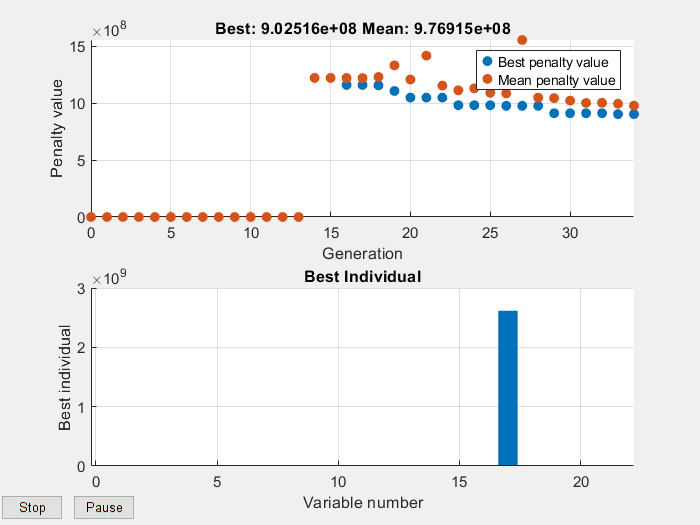

   34             4200       9.025e+08       9.769e+08        1


%Accident Count Parameter Sweep
% values tested: (0, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10)
% GA run 10 times per value


nonlincon = @combinedNonlinconSensitivityTesting;

% set defaults:
minCars = 6;
dist = 35;
maxAccidentCount = 3;

setGlobalConstraintVars(minCars, dist, maxAccidentCount)

%sweep maxAccidentCount hold other two parameters at defaults
x_star_sweep_accidents = [x_initial]; %using x_initial just to set matrix size - probably a better way to do this
fval_sweep_accidents = [];
sweep_vals_accidents = [];

for i = 0:10
    %set constraint values
    setGlobalConstraintVars(minCars, dist, i)

    %run GA 10 times per value
    % for j = 1:10
        [x_star,fval,exitflag,output,population,scores] = ga(fun,nvars,[],[],[],[],lb_total,ub_total,nonlincon,intcon,options);
        
        %save values
        x_star_sweep_accidents(end+1,:) = x_star;
        fval_sweep_accidents(end+1) = fval;
        sweep_vals_accidents(end+1) = i;
    % end
end


fval_sweep_accidents = fval_sweep_accidents';
sweep_vals_accidents = sweep_vals_accidents';

%minCars Parameter Sweep
% values tested: (0, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10)
% GA run 10 times per value
% set defaults:
minCars = 6;
dist = 35;
maxAccidentCount = 3;

setGlobalConstraintVars(minCars, dist, maxAccidentCount)

%sweep minCars hold other two parameters at defaults
x_star_sweep_minCars = [x_initial]; %using x_initial just to set matrix size - probably a better way to do this
fval_sweep_minCars = [];
sweep_vals_minCars = [];

for i = 2:10 %blows up if you do <5?
    %set constraint values
    setGlobalConstraintVars(i, dist, maxAccidentCount)

    %run GA 10 times per value
    for j = 1:10
        [x_star,fval,exitflag,output,population,scores] = ga(fun,nvars,[],[],[],[],lb,ub,nonlincon,intcon,options);
        
        %save values
        x_star_sweep_minCars(end+1, :) = x_star;
        fval_sweep_minCars(end+1) = fval;
        sweep_vals_minCars(end+1) = i;
    end
end

fval_sweep_minCars = fval_sweep_minCars';
sweep_vals_minCars = sweep_vals_minCars';

%plot values
figure()
plot(sweep_vals_dist,fval_sweep_dist)
xlabel("Minimum Distance Between Stations (km)")
ylabel("totalCost")

% %shared variables are: 
% %Output from safety optimization: Vmax (x(21)) --> input to train optimizer
% %Output from train optimization: number of cars (gives mass) (x(16)) ---> parameter in safety optimization 
% 
% %network: (x(1:12))
% %train: (x(13:16))
% %safety: (x(17:21))
% 
% %FPI/MDF:
% %First iteration:
% %set initial placeholders for shared variables
% Vmax_placeholder = 10;
% numcars_placeholder = 16;
% 
% setGlobalVars(Vmax_placeholder,numcars_placeholder)
% %r = getGlobalVars; %for testing 
% 
% % add to beginnning of functions as necessary:
% % [r1, r2] = getGlobalVars;
% % numberofcars = r2;
% % Vmaximum = r1;
% 
% %set epselom (to tune)
% epselom = 0.0001;
% 
% %run GA on network
% [x_network,fval_network,exitflag_network,output_network,population_network,scores_network] = ga(@networkCost,12,[],[],[],[],lb_network,ub_network,nonlincon_network,intcon_network,options);
% 
% %run GA on train
% [x_train,fval_train,exitflag_train,output_train,population_train,scores_train] = ga(@TrainCost,4,[],[],[],[],lb_train,ub_train,nonlincon_train,intcon_train,options);
% 
% %run GA on safety (should be no intcon for this subsystem)
% [x_safety,fval_safety,exitflag_safety,output_safety,population_safety,scores_safety] = ga(@safety_system_cost_function,5,[],[],[],[],lb_safety,ub_safety, nonlincon_safety,intcon,options);
% 
% %enter while loop, compare placeholder to calculated values
% %If not same, iterate until they converge
% while (((Vmax_placeholder - Vmax) > epselom) && ((numcars_placeholder - numcars) > epselom));
%     %reset placeholer values to last calculated value
%     Vmax_placeholder = x_safety(5);
%     numcars_placeholder = x_train(4);
%     setGlobalVars(Vmax_placeholder,numcars_placeholder);
% 
%     %run GA on network
%     [x_network,fval_network,exitflag_network,output_network,population_network,scores_network] = ga(@networkCost,12,[],[],[],[],lb_network,ub_network,nonlincon_network,intcon_network,options);
%     
%     %run GA on train
%     [x_train,fval_train,exitflag_train,output_train,population_train,scores_train] = ga(@TrainCost,4,[],[],[],[],lb_train,ub_train,nonlincon_train,intcon_train,options);
% 
%     %run GA on safety (should be no intcon for this subsystem)
%     [x_safety,fval_safety,exitflag_safety,output_safety,population_safety,scores_safety] = ga(@safety_system_cost_function,5,[],[],[],[],lb_safety,ub_safety, nonlincon_safety,intcon,options);
% end
% 
% %combine for overall x_star and calculate total cost
% x_star = [x_network, x_train, x_safety]
% total_cost = costObj(x_star)



